fs = 44100;  
duration = 3;  
recorder = audiorecorder(fs, 16, 1);  % 16 bits per sample, 1 channel (mono)
disp('Start whistling...');
recordblocking(recorder, duration);
disp('Recording stopped.');

audio_data = getaudiodata(recorder);
audiowrite('reference_audio.wav', audio_data, fs);

% Load the recorded audio
[audio_data, fs] = audioread('reference_audio.wav');

% Compute the FFT
N = length(audio_data);
fft_result = fft(audio_data);
freqs = (0:N-1) * (fs / N);

% Find the fundamental frequency using peak picking (simple threshold)
[yp,id] = max(fft_result)

yp = 1.3152e+03 + 1.8729e+03i

id = 128503

reference_freq = freqs(id)

reference_freq = 42834

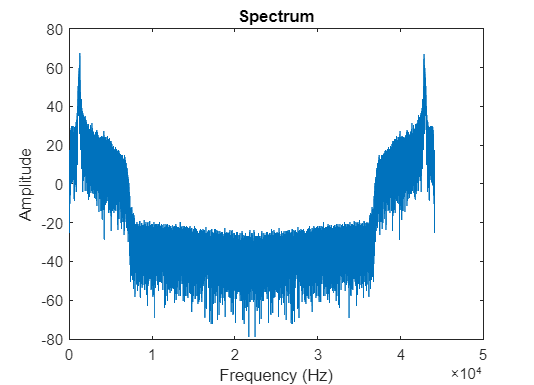


% Plot the spectrum
figure;
plot(freqs, mag2db(abs(fft_result)));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Spectrum');